# Systems Lab: Systems of ODEs in MATLAB

In this lab, you will write your own ODE system solver for the Heun method (aka the Improved Euler method), and compare its results to those of `ode45`.

You will also learn how to save images in MATLAB.

Opening the m-file lab4.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are four (4) exercises in this lab that are to be handed in on the due date of the lab. Write your solutions in a separate file, including appropriate descriptions in each step. Save the m-files and the pdf-file for Exercise 4 and submit them on Quercus.

## Student Information

## Exercise 1

Objective: Write your own ODE system solver using the Heun/Improved Euler Method and compare it to `ode45`.

Details: Consider the system of 2 ODEs:

`x1'=f(t,x1,x2), x2'=g(t,x1,x2)`

This m-file should be a function which accepts as variables (t0,tN,x0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, h is the stepsize, and x0 is a vector for the initial condition of the system of ODEs `x(t0)=x0`. Name the function solvesystem_<UTORid>.m (Substitute your UTORid for [UTORid](http://utorid)). You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB labs 2 and 3).

Your m-file should return a row vector of times and a matrix of approximate solution values (the first row has the approximation for `x1` and the second row has the approximation for `x2`).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

%{

function [x,y]=solvesystem_krisanti(f,g, t0, tN, x0, h) %f,start, endpoint, initial condition, stepsize

x=t0:h:tN;
%disp(x);
size(x)
y=zeros(2, length(x));
y(1,1)=x0(1);
y(2,1)=x0(2);
num=size(x);
for i=1:(num(2)-1)
    kf=f(x(i),y(1,i),y(2,i)); %y(tn+1) = y(n) + (1/2) * h * (f(tn,yn) + f(tn+h, yn+h*f(tn,yn))
    kg=g(x(i),y(1,i),y(2,i));
    x1=y(1,i)+h.*kf;
    x2=y(2,i)+h.*kg;
    y(1, i+1)=(kf+f(x(i+1),x1,x2)).*(1/2).*h   +  y(1,i);
    y(2, i+1)=(kg+g(x(i+1),x1,x2)).*(1/2).*h   +  y(2,i);
end
[ox,oy]=ode45(@(t,y) [f(t, y(1), y(2)); g(t, y(1), y(2))], [t0,tN] ,x0);
%plot(x,y)

%legend("mine", "ode45")
end

%x1' = x1/2 - 2*x2, x2' = 5*x1 - x2
%with initial condition x(0)=(1,1).
%Use your method from Exercise 1 to approximate the solution from t=0 to t=4*pi with step size h=0.05.
 
%}

## Exercise 2

Objective: Compare Heun with an exact solution

Details: Consider the system of ODEs

`x1' = x1/2 - 2*x2, x2' = 5*x1 - x2`

with initial condition `x(0)=(1,1)`.

Use your method from Exercise 1 to approximate the solution from `t=0` to `t=4*pi` with step size `h=0.05`.

Compute the exact solution (by hand) and plot both phase portraits on the same figure for comparison.

Your submission should show the construction of the inline function, the use of your Heun's method to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

x1=@(t,x1, x2) x1/2-2*x2

x1 = function_handle with value:
    @(t,x1,x2)x1/2-2*x2


x2=@(t,x1,x2) 5*x1 - x2

x2 = function_handle with value:
    @(t,x1,x2)5*x1-x2


[x,y]=solvesystem_krisanti(x1, x2, 0, 4*pi, [1,1], 0.05)

ans =      1   252


x =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


y =     1.0000    0.9141    0.8087    0.6869    0.5519    0.4072    0.2565    0.1035   -0.0482   -0.1949   -0.3334   -0.4606   -0.5737   -0.6705   -0.7491   -0.8081   -0.8465   -0.8640   -0.8607   -0.8371   -0.7944   -0.7340   -0.6578   -0.5680   -0.4670   -0.3575   -0.2422   -0.1241   -0.0061    0.1092    0.2191    0.3210    0.4129    0.4927    0.5589    0.6103    0.6460    0.6656    0.6689    0.6565    0.6288    0.5870    0.5324    0.4666    0.3914    0.3088    0.2210    0.1302    0.0385   -0.0517
    1.0000    1.1856    1.3387    1.4563    1.5367    1.5788    1.5826    1.5490    1.4797    1.3772    1.2447    1.0862    0.9059    0.7088    0.4998    0.2843    0.0674   -0.1457   -0.3501   -0.5411   -0.7147   -0.8670   -0.9951   -1.0966   -1.1696   -1.2133   -1.2272   -1.2118   -1.1683   -1.0982   -1.0040   -0.8884   -0.7547   -0.6066   -0.4478   -0.2824   -0.1144    0.0521    0.2132    0.3653    0.5050    0.6293    0.7356    0.8220    0.8868    0.9291    0.9485    0.9449    0.9192    0

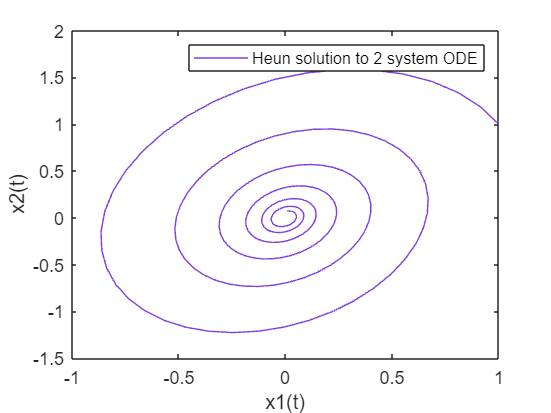

plot(y(1,:),y(2,:))
legend('Heun solution to 2 system ODE')
xlabel('x1(t)')
ylabel('x2(t)')

%exact solution for system with initial condition x(0)=(1 1) is 
%c1=1/20
%c2=17/(20sqrt(151))
%s=sqrt(151)
%o=sqrt(151)/4
%x1=c1exp(-t/4).*(3cos(ot)-s*sin(ot)+c2*exp(-t/4)*(s*cos(ot)+3*sin(ot))
%x1=c1exp(-t/4).*(20*cos(ot)+c2*exp(-t/4)*(20*sin(ot))

## Exercise 3

Objective: Compare your method with Euler's Method (from `iode`).

Details: Use `iode` to plot the solution for the same problem with the same step size as on Exercise 2.

Compare your solution on exercise 2, the exact solution from exercise 2 and the approximation using Euler's method. Plot the solution for Euler's method and make note of any differences.

%euler method using euler.m
fe=@(t,x) [x1(t, x(1), x(2)); x2(t, x(1), x(2))];
t=0:0.05:4*pi

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


eu=euler(fe, [1;1], t)

eu =     1.0000    0.9250    0.8281    0.7117    0.5785    0.4318    0.2749    0.1118   -0.0538   -0.2179   -0.3767   -0.5263   -0.6632   -0.7842   -0.8864   -0.9674   -1.0254   -1.0589   -1.0673   -1.0502   -1.0083   -0.9425   -0.8543   -0.7460   -0.6201   -0.4796   -0.3280   -0.1687   -0.0056    0.1574    0.3165    0.4679    0.6079    0.7334    0.8413    0.9290    0.9946    1.0365    1.0537    1.0459    1.0132    0.9565    0.8772    0.7771    0.6587    0.5248    0.3786    0.2236    0.0635   -0.0979
    1.0000    1.2000    1.3712    1.5097    1.6122    1.6762    1.7003    1.6840    1.6278    1.5329    1.4018    1.2375    1.0441    0.8261    0.5887    0.3377    0.0790   -0.1813   -0.4370   -0.6820   -0.9104   -1.1170   -1.2967   -1.4455   -1.5597   -1.6368   -1.6748   -1.6731   -1.6316   -1.5514   -1.4345   -1.2836   -1.1025   -0.8954   -0.6673   -0.4236   -0.1702    0.0870    0.3418    0.5881    0.8202    1.0325    1.2200    1.3782    1.5036    1.5931    1.6447    1.6571    1.6301    

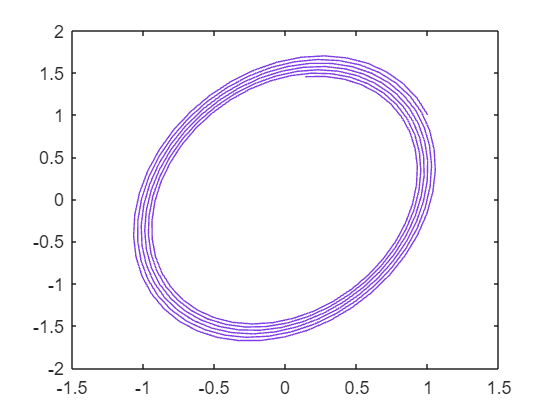

plot(eu(1,:), eu(2,:))

%ex(1,:)

%exact solution
c1=1/20

c1 = 0.0500

c2=17/(20*sqrt(151))

c2 = 0.0692

s=sqrt(151)

s = 12.2882

o=sqrt(151)/4

o = 3.0721

ex1=c1.*exp(-t./4).*(3.*cos(o.*t)-s.*sin(o.*t))+c2.*exp(-t./4).*(s.*cos(o.*t)+3.*sin(o.*t))

ex1 =     1.0000    0.9145    0.8096    0.6885    0.5541    0.4102    0.2601    0.1077   -0.0434   -0.1898   -0.3282   -0.4554   -0.5689   -0.6662   -0.7456   -0.8055   -0.8451   -0.8639   -0.8620   -0.8401   -0.7989   -0.7401   -0.6655   -0.5770   -0.4773   -0.3689   -0.2545   -0.1369   -0.0191    0.0963    0.2066    0.3093    0.4022    0.4835    0.5514    0.6047    0.6425    0.6644    0.6702    0.6601    0.6349    0.5954    0.5429    0.4791    0.4056    0.3244    0.2376    0.1474    0.0560   -0.0345


ex2=c1.*exp(-t./4).*(20.*cos(o.*t))+c2.*exp(-t./4).*(20.*sin(o*t))

ex2 =     1.0000    1.1850    1.3377    1.4553    1.5359    1.5786    1.5832    1.5507    1.4827    1.3817    1.2508    1.0939    0.9152    0.7195    0.5119    0.2973    0.0811   -0.1317   -0.3361   -0.5276   -0.7021   -0.8557   -0.9856   -1.0892   -1.1647   -1.2111   -1.2281   -1.2158   -1.1754   -1.1084   -1.0172   -0.9044   -0.7733   -0.6272   -0.4701   -0.3059   -0.1385    0.0279    0.1896    0.3429    0.4843    0.6110    0.7202    0.8098    0.8783    0.9245    0.9479    0.9486    0.9270    0.8843


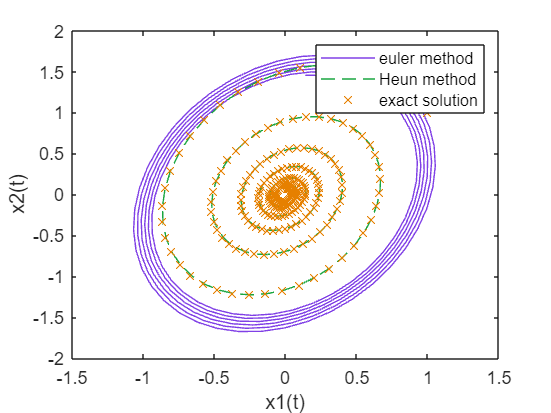


%plotting it all together
plot(eu(1,:), eu(2,:),y(1,:),y(2,:),'--', ex1,ex2, 'x')
legend("euler method", "Heun method", "exact solution")
xlabel('x1(t)')
ylabel('x2(t)')



%Both Heun and exact solution shows the 0,0 point. From the initial condition, 
%the exact solution and Heun method approaches 0,0 by moving counterclockwise while the 
%The Euler method did not reach that point, it has a larger error and
%overshoots in the beginning.

## Saving Images in MATLAB

To do the following exercises, you will need to know how to output graphics from MATLAB. Create a folder on your Desktop (or elsewhere) to contain the files generated by these exercises. Make this folder the "Current Folder" in the left side of the main MATLAB window. This will ensure that the files output by MATLAB end up in the folder you created.

To save an image of a phase portrait, use the following steps:

1. Get the phase portrait looking the way you want in the `iode` window. 

2. Leaving `iode` open, switch to the main MATLAB window.

3. Type the command `print -dpng -r300 'filename.png'` in the command window.

This command will create a PNG graphic called `filename.png` in the current folder. The `-dpng` option tells MATLAB to output the graphic in PNG format; MATLAB also allows output in other formats, such as BMP, EPS, PNG and SVG. The `-r300` option tells MATLAB to set the resolution at 300 dots per inch and can be adjusted if you wish.

## Exercise 4

Objective: Analyze phase portraits.

Details: Compile the results of the following exercises into a single document (e.g. using a word processor) and export it to `PDF` for submission on Quercus. 

For each of the first-order systems of ODEs 4.1 to 4.10 below, do the following exercises:

(a) Generate a phase portrait for the system (centre the graph on the equilibrium point at (0,0)). Include a few trajectories.

(b) Classify the equilibrium on asymptotic stability, and behaviour (sink, source, saddle-point, spiral, center, proper node, improper node) - check table 3.5.1 and figure 3.5.7. Classify also as for clockwise or counterclockwise movement, when relevant.

(c) Compute the eigenvalues of the matrix (you do not need to show your calculations). Using the eigenvalues you computed, justify part (b).

To avoid numerical error, you should use Runge-Kutta solver with a step size of `0.05`. Change the display parameters, if necessary, to best understand the phase portrait.

4.1. `dx/dt = [2 1; 1 3] x`

4.2. `dx/dt = [-2 -1; -1 -3] x`

4.3. `dx/dt = [-4 -6; 3 5] x`

4.4. `dx/dt = [4 6; -3 -5] x`

4.5. `dx/dt = [0 -1; 1 -1] x`

4.6. `dx/dt = [0 1; -1 1] x`

4.7. `dx/dt = [2 8; -1 -2] x`

4.8. `dx/dt = [-2 -8; 1 2] x`

4.9. `dx/dt = [-8 5; -13 8] x`

4.10. `dx/dt = [8 -5; 13 -8] x`